# Extracción de características de audio:

[audio, fs] = audioread('audio/doviso/toma_larga_behringer.wav'); 
% Si es estéreo, convertir a mono
if size(audio,2) > 1
    audio = mean(audio, 2);
end

y = audio;
L = length(y);
tiempo = (0:L-1)/fs;


% Parámetros de tramas
ttrama = 0.1;              % Duración de trama en segundos
ltrama = round(fs * ttrama); % Longitud de trama en muestras
Ntramas = floor(L / ltrama);

SC = zeros(1, Ntramas);
Zcr = zeros(1, Ntramas);
e = zeros(1, Ntramas);
krt = zeros(1, Ntramas);

tiempo_t = (0:Ntramas-1)*ttrama;

for ii = 1:Ntramas
    idx_start = (ii-1)*ltrama + 1;
    idx_end = idx_start + ltrama - 1;
    yn = y(idx_start:idx_end);
    yn_norm = st_normalize(yn);
    
    SC(ii) = sc(yn_norm, fs, ltrama);
    Zcr(ii) = zcr(yn_norm);
    e(ii) = sum(yn.^2) / ltrama;
    krt(ii) = kurtosis(yn_norm);
end


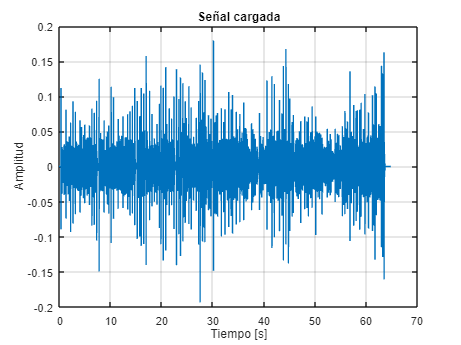

% Graficar señal original
figure;
plot(tiempo, y);
xlabel('Tiempo [s]');
ylabel('Amplitud');
grid on;
title('Señal cargada');

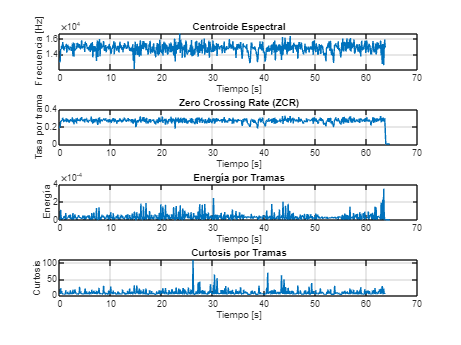


% Graficar características por tramas
figure;
subplot(4,1,1);
plot(tiempo_t, SC);
xlabel('Tiempo [s]');
ylabel('Frecuencia [Hz]');
title('Centroide Espectral');
grid on;

subplot(4,1,2);
plot(tiempo_t, Zcr);
xlabel('Tiempo [s]');
ylabel('Tasa por trama');
title('Zero Crossing Rate (ZCR)');
grid on;

subplot(4,1,3);
plot(tiempo_t, e);
xlabel('Tiempo [s]');
ylabel('Energía');
title('Energía por Tramas');
grid on;

subplot(4,1,4);
plot(tiempo_t, krt);
xlabel('Tiempo [s]');
ylabel('Curtosis');
title('Curtosis por Tramas');
grid on;

function y = sc(x, fs, N)
    % Cálculo de Centroide Espectral
    L = length(x);
    x = reshape(x, L, 1);
    X = abs(fft(x, N))';
    f = (0:(N-1)) * fs / N;
    n = floor(N/2);
    y = sum(X(1:n).*f(1:n)) / sum(X(1:n));
end

function y = st_normalize(x)
    % Normaliza la señal: divide por std y centra en 0
    y = x / std(x);
    y = y - mean(y);
end

function y = zcr(x)
    % Cálculo de Zero Crossing Rate
    L = length(x);
    y = sum(abs(diff(x > 0))) / L;
end

